% Generalized script for Shimadzu Outputs
% CMikolaitis, 2022
clear, clc, %clf

## Input wrapper

InputName = ['Chris TNDOC 012624 Detail'];
filename = [InputName '.txt'];

## Open File

opts = detectImportOptions(filename);
% set column 3 (named 'SampleName' and 'SampleID') data to type 'char', i.e. import it as a character array
opts.VariableTypes{1,3} = 'char';
opts.VariableTypes{1,4} = 'char';
% set time units
opts = setvaropts(opts,opts.VariableNames(9),'InputFormat','MM/dd/uuuu hh:mm:ss aa');
DATA = readtable(filename, opts);

## Clean Data

Clean up blanks at start

while DATA.Type{1} == "Unknown"
    DATA(1,:) = [];
end
% Clean up standards that don't correspond to samples
i = 1;
while DATA.Type{i} == "Standard"
    if strcmp(DATA.Anal_{i},DATA.Anal_{i+1})
        i = i+1;
    else
        DATA(1:i,:) = [];
        break
    end
end
% Clean up failed standard runs
i = 1;
terminaldex = 0;
while DATA.Type{i} == "Standard"
    if DATA.Spl_No_(i) > DATA.Spl_No_(i+1) && DATA.Type{i+1} == "Standard"
        terminaldex = i;
    end
    i = i+1;
end
if terminaldex > 0
    DATA(1:terminaldex,:) = [];
end

## Manually delete any bad data & Remove excluded values

2/14/26 Note: Added automated removal of excluded values, still does not adjust for manually excluded standards.

exDEX = logical(DATA.Excluded);
DATA(exDEX,:) = [];

%standards(1:5,:) = [];

## Split Data

Get point at which 2nd standards are run

AnalyteGroups    = findgroups(DATA.Anal_);
breakpoint       = ischange(double(AnalyteGroups));
numberofanalytes = 1+sum(breakpoint);
% Break table at analyte groups
cleanedDATA      = cell(1,numberofanalytes);
for i = 1:numberofanalytes
    for j = 1:height(DATA)
        if AnalyteGroups(j) == i
            cleanedDATA{i} = [cleanedDATA{i};DATA(j,:)];
        end
    end
end

## The Loop that does everything

for i = 1:numberofanalytes

## Get sample types (mainly will be 'Standard' or 'Unknown')

    idx_Std          = strcmp(cleanedDATA{i}.Type,'Standard');
    idx_Unk          = strcmp(cleanedDATA{i}.Type,'Unknown');
    standards        = cleanedDATA{i}(idx_Std,:);
    unknowns         = cleanedDATA{i}(idx_Unk,:);

## Get standard concentration and peak area

    std_conc         = standards.Conc_;
    std_area         = standards.Area;
    std_conc_means   = groupsummary(std_conc,standards.Spl_No_,'mean');
    std_area_means   = groupsummary(std_area,standards.Spl_No_,'mean');

## Plot standard curve

2/16/24 Note: TOC software uses ordinary R-squared, not adjusted. Issue resolved as of today.

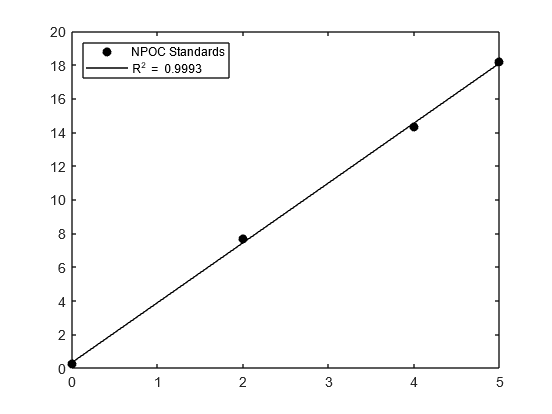

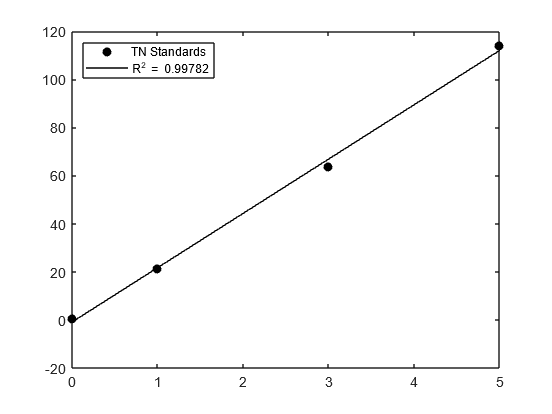

    figure;
    y = std_area_means;
    x = std_conc_means;
    plot(x,y,'ok','markerfacecolor','k')
    mdl = fitlm(x,y);
    hold on
    plot(x,mdl.Fitted,'-k')
    analytefill = append(standards.Anal_{1},' Standards');
    legend(analytefill,['R^2 = ' num2str(mdl.Rsquared.Ordinary)],'location','northwest')

## Plot QA data high and low standards, spikes, and natural sample

concatenate 'SampleName' and 'SampleID' columns

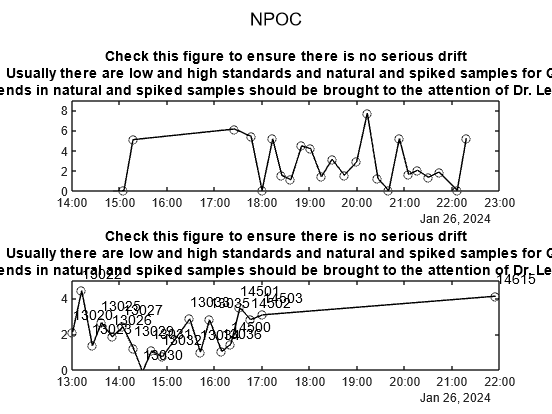

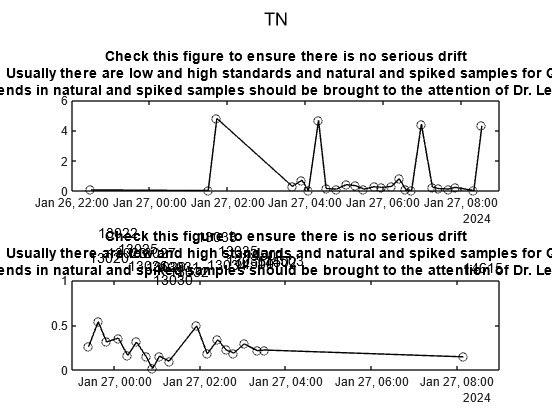

    clear Sample_name_ID
    for i = 1:size(unknowns,1)
        if size(unknowns.SampleID{i,1},1) == 0
            Sample_name_ID{i,1} = [unknowns.SampleName{i,1}];
        else
            Sample_name_ID{i,1} = [unknowns.SampleName{i,1}, '-', unknowns.SampleID{i,1}];
        end
    end
    % find indices for when Sample_name_ID changes
    clear temp
    temp(:,1) = Sample_name_ID;
    temp(end+1,:) = {'nan'};
    temp(end+1,1) = {'nan'};
    temp(1,2) = {'nan'};
    temp(2:end,2) = temp(1:end-1,1);
    %ChangeInID = ismember(temp_stn(:,1),temp_stn(:,2),'rows');
    ChangeInID = find(strcmp(temp(:,1),temp(:,2))==0);
    ChangeInID(1:end-1,2) = ChangeInID(2:end,1)-1;
    ChangeInID(end,:) = [];
    Sample_name_ID_unique = Sample_name_ID(ChangeInID(:,1));
    
    % Initialize arrays with mean values to be plotted
    clear idx_QA DIC_QA t_QA DIC_sample t_sample
    panicbutton = 1;
    for i = 1:size(Sample_name_ID_unique,1)
        if isempty(str2num(Sample_name_ID_unique{i,1}))
            idx_QA(i,1) = 0; % characters
            DIC_QA(i,1) = mean(unknowns.Conc_(ChangeInID(i,1):ChangeInID(i,2),1));
            t_QA(i,1)   = unknowns.Date_Time(ChangeInID(i,1),1);
            panicbutton = 0;
        else
            idx_QA(i,1)     = 1; % numbers
            DIC_sample(i,1) = mean(unknowns.Conc_(ChangeInID(i,1):ChangeInID(i,2),1));
            t_sample(i,1)   = unknowns.Date_Time(ChangeInID(i,1),1);
        end
    end
    
    % Plot QA
    figure;
    subplot(2,1,1)
    if panicbutton == 0
        t = t_QA(find(idx_QA == 0));
        y = DIC_QA(find(idx_QA == 0));
        text(t,y,Sample_name_ID_unique(find(idx_QA == 0)));
        ymax = round(max(y(:))*1.2);
    else
        t = 0;
        y = 0;
        text(t,y,'DRIFT CHECK NOT AVAILABLE');
        ymax = round(max(y(:))+1);
    end
    plot(t,y,'-ok')
    
    set(gca,'ylim',[0 ymax])
    title([{'Check this figure to ensure there is no serious drift'};...
        {'Usually there are low and high standards and natural and spiked samples for QA'};...
        {'Trends in natural and spiked samples should be brought to the attention of Dr. Lehrter'}]);
    
    % Plot Samples
    subplot(2,1,2)
    t = t_sample(find(idx_QA == 1));
    y = DIC_sample(find(idx_QA == 1));
    plot(t,y,'-ok')
    text(t,y+1,Sample_name_ID_unique(find(idx_QA == 1)));
    ymax = round(max(y(:))*1.2);
    set(gca,'ylim',[0 ymax])
    title([{'Check this figure to ensure there is no serious drift'};...
        {'Usually there are low and high standards and natural and spiked samples for QA'};...
        {'Trends in natural and spiked samples should be brought to the attention of Dr. Lehrter'}]);
    varnames =  {'SampleName','Date_time','Conc_mg_L'};
    sgtitle(standards.Anal_{1});
    % % varnames = {'Id','yyyymmdd','decy','time','latN','lonW', 'Depth','Temp','Pres','CTD_S','Sal1','Sig_th','O2_1','OxFixT','Anom1'};

## Generate Excel Sheet

TNDOC is the accepted naming convention for multianalyte runs

    excelname = InputName;
    temp      = standards.Anal_{1};
    if temp == "TN"
        excelname(3:5) = [];
    elseif temp == "NPOC"
        excelname(1:2) = [];
    end
    filename_excel = [excelname '.xlsx'];
    T_name = table({excelname});
    % T_Excel_out.Properties.VariableNames = varnames;
    T_Excel_out = table(Sample_name_ID_unique(find(idx_QA == 1)),t,y);
    T_Excel_out.Properties.VariableNames = varnames;
    writetable(T_name,filename_excel,'Sheet',1,'Range','A1','WriteVariableNames',false);
    writetable(T_Excel_out,filename_excel,'Sheet',1,'Range','A2');
end